clc, clear, close all
syms a x

% %% f1 
% f = a*x^2 - 2*(a+1)*x + 3*a - 1
% df = diff(f, x)
% r = solve(f, x)
% 
% a_bifurc = (solve((r(1,1)-r(2,1))))
% 
% 
% sr = subs(df, x, r)
% df_m = subs(sr, a, -0.2)
% df_p = subs(sr, a, 0.25)
% 
% sr_m = subs(r, a, -0.15)
% sr_p = subs(r, a, 0.25)
% 
% figure(1)
% hold on
% 
% fplot(r(1,1))
% fplot(r(2,1))
% 
% plot(-0.15,sr_m(1,1), "square", "color", 'k', 'MarkerSize',10)
% plot(-0.15,sr_m(2,1), "o", "color", 'k', 'MarkerSize',10)
% plot(0.25,sr_p(1,1), "square", "color", 'k', 'MarkerSize',10)
% plot(0.25,sr_p(2,1), "o", "color", 'k', 'MarkerSize',10)
% annotation('arrow',[0.237 0.237],[0.29 0.7])
% annotation('arrow',[0.36 0.36],[0.29 0.7])
% xlim([-0.5 2])
% ylim([-40 40])
% grid on
% xlabel('a')
% ylabel('x')
% legend('неустойчиво','устойчиво','С.Р.1','С.Р.1','С.Р.2','С.Р.2')
% hold off



%f2
f = (a-1)*9^x - 2*a*3^x + 2*a + 2

$$f = 2\,a-2\,3^{x}\,a+9^{x}\,\left(a-1\right)+2$$

df = (diff(f, x))

$$df = 9^{x}\,\log\left(9\right)\,\left(a-1\right)-2\,3^{x}\,a\,\log\left(3\right)$$

r = simplify(solve(f, x))

$$r = \left(\begin{array}{c} \frac{\log\left(\frac{a-\sqrt{2-a^{2}}}{a-1}\right)}{\log\left(3\right)}\\ \frac{\log\left(\frac{a+\sqrt{2-a^{2}}}{a-1}\right)}{\log\left(3\right)} \end{array}\right)$$


rr = (r(1,1)-r(2,1))

$$rr = \frac{\log\left(\frac{a-\sqrt{2-a^{2}}}{a-1}\right)}{\log\left(3\right)}-\frac{\log\left(\frac{a+\sqrt{2-a^{2}}}{a-1}\right)}{\log\left(3\right)}$$

a_bifurc = solve(rr)

$$a\_bifurc = \left(\begin{array}{c} \sqrt{2}\\ -\sqrt{2} \end{array}\right)$$

sr = subs(df, x, r);
df_m = eval((subs(sr, a, -1.25)))

df_m =    -1.2346
    0.3802


df_p = eval((subs(sr, a, 1.25)))

df_p =    -3.4215
   11.1118


df_0 = eval((subs(sr, a, 0)))

df_0 =   -4.3944 + 0.0000i
  -4.3944 - 0.0000i



sr_m = eval(subs(r, a, -1.25))

sr_m =    -0.1484
   -1.2206


sr_p = eval(subs(r, a, 1.25))

sr_p =     0.7794
    1.8516


sr_0 = eval(subs(r, a, 0))

sr_0 =    0.3155 + 0.0000i
   0.3155 + 2.8596i


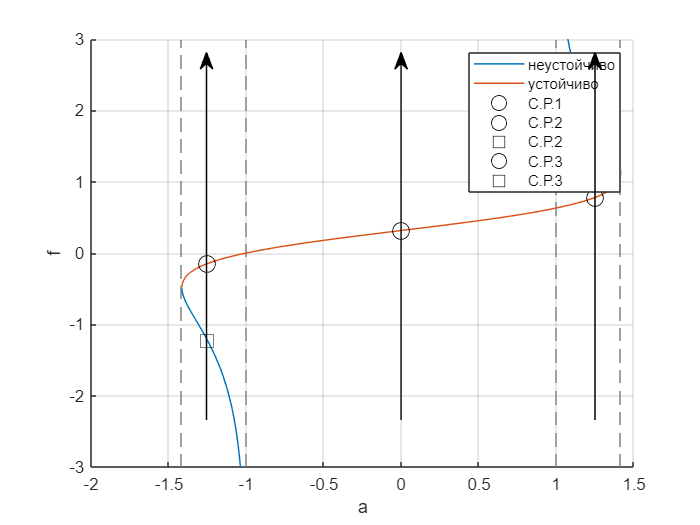


figure(2)
hold on
fplot(r(2,1))
fplot(r(1,1))



plot(0,sr_0(1,1), "o", "color", 'k', 'MarkerSize',10)

plot(-1.25,sr_m(1,1), "o", "color", 'k', 'MarkerSize',10)
plot(-1.25,sr_m(2,1), "square", "color", 'k', 'MarkerSize',10)

plot(1.25,sr_p(1,1), "o", "color", 'k', 'MarkerSize',10)
plot(1.25,sr_p(2,1), "square", "color", 'k', 'MarkerSize',10)

annotation('arrow',[0.295 0.295],[0.2 0.9])
annotation('arrow',[0.573 0.573],[0.2 0.9])
annotation('arrow',[0.85 0.85],[0.2 0.9])

legend('неустойчиво','устойчиво','С.Р.1','С.Р.2','С.Р.2','С.Р.3','С.Р.3')
xlim([-2 1.5])
ylim([-3 3])
grid on
xlabel('a')
ylabel('f')
hold off